# Geometry of Top Brass

max_{f,s} 12f + 9s

s.t. 4f + 2s <= 4800

       f + s <= 1750

      0 <= f <= 1000

      0 <= s <= 1500

s1 = @(f) -2*f+ 2400;
s2 = @(f) -f + 1750;
s3 = @(f) 0*f + 1500;


f = 0:1:1750;
pgon1 = polyshape([0 f f(end)],[0 s1(f) -1100],'Simplify',false); 
pgon2 = polyshape([0 f f(end)],[0 s2(f) 0], 'Simplify', false);
pgon3 = polyshape([0 0 1000 1000],[0 1500 1500 0], 'Simplify', false);
%pgon4 = polyshape([0 0 1000 1000],[0 1500 1500 0], 'Simplify', false)


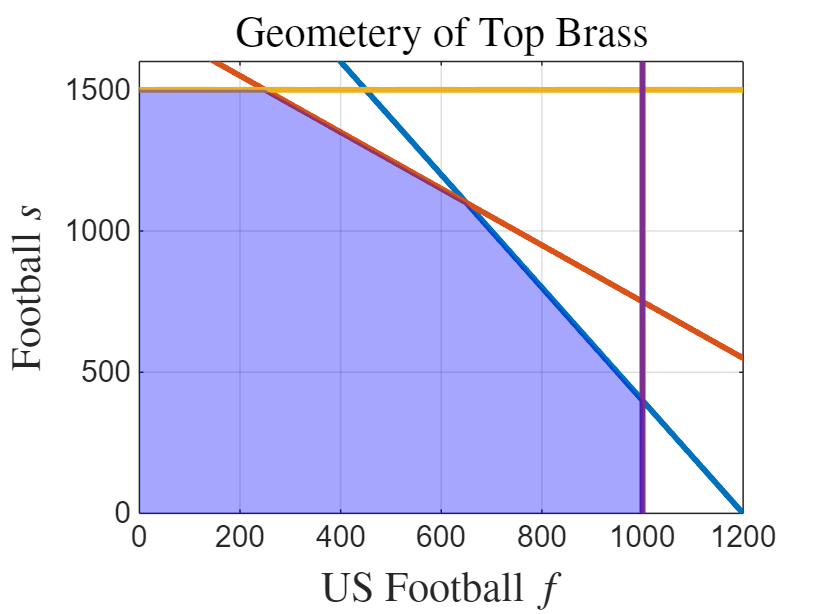

figure(1)
clf
plot(f, s1(f), f, s2(f), f, s3(f), 'LineWidth', 2); grid
hold on
plot([1000, 1000], [0 1600], 'LineWidth', 2)
plot(intersect([pgon1, pgon2, pgon3]),...
    'EdgeColor','none', 'FaceColor','blue');
axis([0 1200 0 1600])
xlabel("US Football $f$", 'Interpreter','latex','FontSize', 14);
ylabel("Football $s$", 'Interpreter','latex','FontSize', 14);
title("Geometery of Top Brass", 'FontSize',14, 'Interpreter','latex');
hold off

% cvx 
% cvx_begin
%     variables f s
%     %variable s
% 
%     maximize (12*f + 9*s)
% subject to
%     4*f + 2*s <= 4800
%     f + s <= 1750
%     0 <= f <= 1000
%     0 <= s <= 1500
% cvx_end

 
Calling Mosek 9.1.9: 6 variables, 2 equality constraints
   For improved efficiency, Mosek is solving the dual problem.
------------------------------------------------------------

MOSEK Version 9.1.9 (Build date: 2019-11-21 11:34:40)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : LO (linear optimization problem)
  Constraints            : 2               
  Cones                  : 0               
  Scalar variables       : 6               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2   


% fprintf("The optimal value of f is %1.4f",f)

The optimal value of f is 650.0000

% fprintf("The optimal value of s is %1.4f", s)

The optimal value of s is 1100.0000

% fprintf("The cost function is %1.4f", 12*f + 9*s)

The cost function is 17700.0000

% Objective function (note: linprog minimizes, so we negate the coefficients)
f_obj = [-12; -9];  % Maximize becomes minimize of negative

% Inequality constraints: A*x ≤ b
A = [4, 2;
     1, 1];
b = [4800;
     1750];

% Variable bounds
lb = [0; 0];         % Lower bounds for f and s
ub = [1000; 1500];   % Upper bounds for f and s

% Solve using linprog
options = optimoptions('linprog','Display','none');  % Suppress output
[x_opt, fval] = linprog(f_obj, A, b, [], [], lb, ub, options);

% Display results
f = x_opt(1);
s = x_opt(2);
max_profit = -fval;  % Negate to get the original maximized value

fprintf('Optimal f: %.2f\n', f);

Optimal f: 650.00


fprintf('Optimal s: %.2f\n', s);

Optimal s: 1100.00


fprintf('Maximum profit: %.2f\n', max_profit);

Maximum profit: 17700.00
